% Constants for Rb-87
Gamma = 2 * pi * 6.065e6; % Natural linewidth in Hz for Rb-87 D2 line
h_bar = 1.0545718e-34; % Reduced Planck constant in J*s
m = 87 * 1.66053906660e-27; % Mass of the atom in kg (Rubidium-87)
w_push = 0.004; % Beam waist in meters
w_2D = 0.035; % 2D MOT beam waist
W_repump = 0.035; % Repumping beam waist
mu_B = 9.274009994e-24; % Bohr magneton in J/T
b = 0.1; % Magnetic field gradient in T/m (example value)
k_B = 1.380649e-23; % Boltzmann constant in J/K
T = 450; % Temperature in K
I_sat = 1.667; % Saturation intensity for Rb-87 in mW/cm^2

% Initialization parameters
N_sim = 20000; % Number of simulated atoms
t_tot = 4e-4; % Total simulation time in seconds
dt = 5e-5; % Time step in seconds
v_cap = 30; % More realistic MOT capture velocity in m/s
r_cap = 0.01; % More realistic MOT capture radius in meters
tau_coll = 0.05; % Collision time scale in seconds
I_2D = 10; % 2D MOT beam intensity in mW/cm^2
delta_2D = -7*Gamma; % Cooling light detuning in Hz
I_repump = 1; % Repumping beam intensity in mW/cm^2
delta_repump = -2*Gamma; % Repumping light detuning in Hz
I_push = 1; % Push beam intensity, assumed constant

% Range of push beam detunings to scan
delta_push_range = -10 * Gamma:0.5 * Gamma:0; % Example range

% Store capture efficiencies
capture_efficiencies = zeros(size(delta_push_range));

% Monte Carlo simulation for each detuning value
for k = 1:length(delta_push_range)
    delta_push = delta_push_range(k); % Current push beam detuning
    captured = false(N_sim, 1);

    % Generate initial conditions from oven (Maxwell-Boltzmann distribution)
    speeds = abs(sqrt(k_B * T / m) * randn(N_sim, 1)); % Initial speeds in m/s
    angles = 2 * pi * rand(N_sim, 2); % Random angles for direction
    positions = zeros(N_sim, 3); % Initial positions at the oven exit
    velocities = speeds .* [cos(angles(:, 1)) .* sin(angles(:, 2)), sin(angles(:, 1)) .* sin(angles(:, 2)), cos(angles(:, 2))]; % Initial velocities

    % Define the direction of the wave vector k for cooling beams and push beam
    k_2D = [1, 0, 0; -1, 0, 0; 0, 1, 0; 0, -1, 0]; % Four wave vectors for the 2D MOT
    k_push = [0, 0, 1]; % Wave vector direction of the push beam

    % Simulation loop
    for i = 1:N_sim
        for t = 0:dt:t_tot
            % Calculate acceleration
            a_2D = [0, 0, 0];
            for j = 1:4
                % 2D MOT acceleration
                s2D = calculate_s(positions(i, :), k_2D(j, :), I_2D, I_sat, w_2D);
                delta_eff_2D = calculate_delta_eff(delta_2D, k_2D(j, :), ...
                    velocities(i, :), positions(i, :), b, mu_B, h_bar);
                R_2D = calculate_R(s2D, delta_eff_2D, Gamma);
                e_2D = randn(1, 3); % Random vector for scattering
                a_2D = a_2D + (h_bar * norm(k_2D(j, :)) * Gamma / (2 * m)) *...
                (abs(R_2D) / 4) * (k_2D(j, :) + e_2D * sqrt(R_2D * dt / 4));
            end

            % Repumping beam acceleration (assuming similar direction as cooling beams)
            a_repump = [0, 0, 0];
            for j = 1:4
                s_repump = calculate_s(positions(i, :), k_2D(j, :), ...
                    I_repump, I_sat, W_repump);
                delta_eff_repump = calculate_delta_eff(delta_repump, ...
                    k_2D(j, :), velocities(i, :), positions(i, :), b, mu_B, h_bar);
                R_repump = calculate_R(s_repump, delta_eff_repump, Gamma);
                e_repump = randn(1, 3); % Random vector for scattering
                a_repump = a_repump + (h_bar * norm(k_2D(j, :)) * ...
                    Gamma / (2 * m)) * (abs(R_repump) / 4) * (k_2D(j, :) + ...
                    e_repump * sqrt(R_repump * dt / 4));
            end

            % Push beam acceleration
            s_push = I_push / I_sat; % Assuming constant push beam intensity
            delta_eff_push = calculate_delta_eff(delta_push, k_push, velocities(i, :), positions(i, :), b, mu_B, h_bar);
            R_push = calculate_R(s_push, delta_eff_push, Gamma);
            e_push = randn(1, 3); % Random vector for scattering
            a_push = (h_bar * norm(k_push) * Gamma / (2 * m)) *...
            (abs(R_push) / 4) * (k_push + e_push * sqrt(R_push * dt / 4));

            % Euler method to update velocities and positions
            velocities(i, :) = velocities(i, :) + (a_2D + a_repump + a_push) * dt;
            positions(i, :) = positions(i, :) + velocities(i, :) * dt;
        end

        % Capture condition
        if norm(velocities(i, :)) < v_cap && norm(positions(i, :)) < r_cap
            captured(i) = true;
        end

        % Collision condition
        p_coll = 1 - exp(-t_tot / tau_coll);
        epsilon = rand;
        if epsilon < p_coll
            captured(i) = false; % Collision results in loss of capture
        end
    end

    % Calculate capture efficiency for the current detuning
    capture_efficiencies(k) = sum(captured) / N_sim;
    
end

% Find the best detuning
[~, best_index] = max(capture_efficiencies);
best_delta_push = delta_push_range(best_index);

disp(['Best push beam detuning: ', num2str(best_delta_push / 1e6), ' MHz']);

Best push beam detuning: -342.9677 MHz


disp(['Highest capture efficiency: ', num2str(capture_efficiencies(best_index))]);

Highest capture efficiency: 0.089


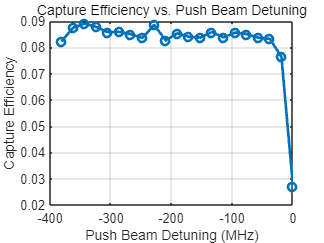


% Plotting the capture efficiency vs. push beam detuning
figure;
plot(delta_push_range / 1e6, capture_efficiencies, 'o-', 'LineWidth', 2);
title('Capture Efficiency vs. Push Beam Detuning');
xlabel('Push Beam Detuning (MHz)');
ylabel('Capture Efficiency');
grid on;


% Helper function to calculate deceleration force R (Formula 4)

function R = calculate_R(s, delta_eff, Gamma)
    % s: Saturation parameter
    % delta_eff: Effective detuning
    % Gamma: Natural linewidth
    
    % Calculate R (deceleration force)
    R = (Gamma / 2) * (s / (1 + s + (2 * delta_eff / Gamma)^2));
end

% Function to calculate saturation parameter s (Formula 5)
function s = calculate_s(r, k, I, I_sat, w)
    % r: Position of the atom
    % k: Wave vector
    % I: Beam intensity
    % I_sat: Saturation intensity
    % w: Beam waist
    
    % Calculate distance from the beam center
    r_perp = norm(cross(r, k)) / norm(k);
    % Calculate s (saturation parameter)
    s = (I / I_sat) * exp(-2 * r_perp^2 / w^2);
end

% Function to calculate effective detuning delta_eff (Formula 6)
function delta_eff = calculate_delta_eff(delta, k, v, r, b, mu_B, h_bar)
    % delta: Initial detuning
    % k: Wave vector
    % v: Velocity of the atom
    % r: Position of the atom
    % b: Magnetic field gradient
    % mu_B: Bohr magneton
    % h_bar: Reduced Planck constant
    
    % Calculate magnetic field at position r
    B = b * norm(r); % Simple linear quadrupole field
    
    % Calculate effective detuning
    delta_eff = delta + dot(k, v) - (mu_B * B / h_bar);
end
